# Preamble

clc, clear;

## Includes

addpath("../auxiliary/");
addpath("C:\ApostolatosFork\cane\generalMath");

## Analytical solution

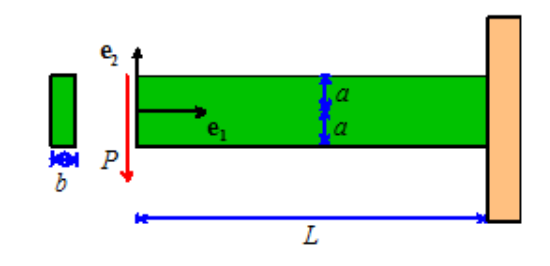

E = 1e7;
v = 0.31;
b=0.05; %thickness
a=0.2;
c=0;
P=1000000;
L=4;

d= (-P*L^3)/(2*E*a^3*b);
w = (3*P*L^2)/(4*E*a^3*b);

syms x1 x2 U1(x1, x2) U2(x1,x2) 
U1(x1, x2) = (3*P*(x1.^2).*x2-P*x2.^3*(2+v))/(4*E*a^3*b)+(3*P*a^2*x2)/(2*E*a^3*b) - w*x2 + c;
U2(x1, x2) = (-v*3*P*x1.*x2.^2-P*x1.^3)/(4*E*a^3*b) +w*x1 + d;
U_analytical = [U1;U2];

## Define the problem parameters

% Amplitude at the beam's ends
w0 = 0;
% possiblePenaltyFactor=0;
% calculateNorms = 0;
% iterator = 0;
%material
propStruct.E = 1e7;
propStruct.v = 0.31;
propStruct.p = 7750*1e1; %kg/m3 (steel)
propStruct.g = 9.81; %(m/s2)

% Computational domain
propGeom.X0 = 0;
propGeom.XL = 4;
XComp = [propGeom.X0 propGeom.XL];

propGeom.Y0=0;
propGeom.YL=1;
YComp = [propGeom.Y0 propGeom.YL];


% Test cooordinates transformation
results = coordinateTransformationToXiAndEta(XComp',YComp');
results.scale_x;
results.const_x;
results.scale_y;
results.const_y;
detJ = determinantOfJacobian(results);

## Generate the training data

% points over which to enforce the boundary conditions by means of the loss
% of the neural network
numBC = 32;

% boundary conditions
% W(x=0 , y) = 0
X0BC = propGeom.XL * ones(1,numBC);
Y0BC = linspace(propGeom.Y0, propGeom.YL , numBC);
U0BC = w0*ones(2, numBC);

X_Neumann = propGeom.X0 * ones(1,numBC);
Y_Neumann = linspace(propGeom.Y0, propGeom.YL , numBC);

## Create some random points between the computational interval

numInternColl = 4*numBC^2;
pointSet = sobolset(2);
points = net(pointSet,numInternColl);
X = (XComp(1, 1) + points(:, 1)*(XComp(1, 2) - XComp(1, 1)))';
Y = (YComp(1, 1) + points(:, 2)*(YComp(1, 2) - YComp(1, 1)))';

## Find optimal penalty factor (PART A)

C = (propStruct.E /(1-propStruct.v^2))*[
    1 propStruct.v 0;
    propStruct.v 1 0;
    0 0 (1-propStruct.v)/2];

%% median value for the logspace vector
initFactor = norm(C)*numInternColl/numBC;

%% use logspace
vectorStart = 2*initFactor*1e-10;
vectorStop = 2*initFactor*1e+10;
logSpaceA = log10(vectorStart);
logSpaceB = log10(vectorStop);

possiblePenaltyFactor = logspace(logSpaceA, logSpaceB, 3);
calculateNorms = zeros(length(possiblePenaltyFactor), 1);

for iterator = 1:length(possiblePenaltyFactor)

## Deep learning model

% % Number of layers and Number of neurons per layer
numLayers = 5;
numNeurons = 15;

%%Create parameters as a struct
parameters = struct;

sz = [numNeurons 2];

% % initialize the weights and biases for the first fully connected operation
% The input layer has 2 neurons and numNeurons connections to the next layer
 parameters.fc1_Weights = initializeHe(sz, 2, "double");
 parameters.fc1_Bias = initializeZeros([numNeurons 1],"double");

% % Initialize the weights and biases for the hidden fully connected operations.
for layerNumber = 2:numLayers-1
    name = "fc"+layerNumber;

    sz = [numNeurons numNeurons];
    parameters.(name+"_Weights") = initializeHe(sz, numNeurons, "double");
    parameters.(name+"_Bias") = initializeZeros([numNeurons 1], "double");
end
 
% % Initialize the final fully connected operation. The output layer has 2 
% %  neurons and returns the predicted solution u(x,y) and w(x,y)
sz = [2 numNeurons];
parameters.("fc" + numLayers +"_Weights") = initializeHe(sz, numNeurons, "double");
parameters.("fc" + numLayers + "_Bias") = initializeZeros([2 1],"double");

## Test the initialized network

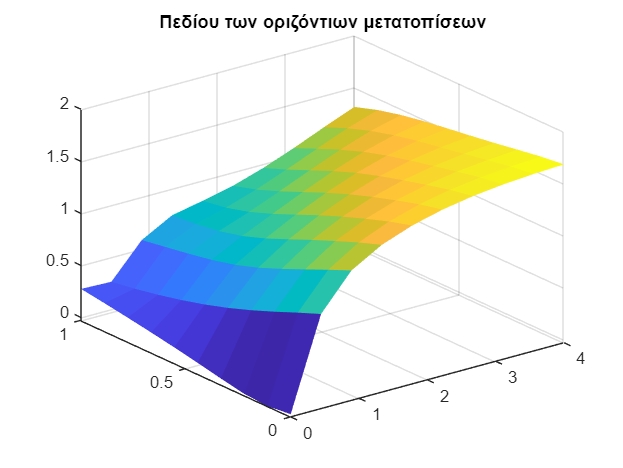

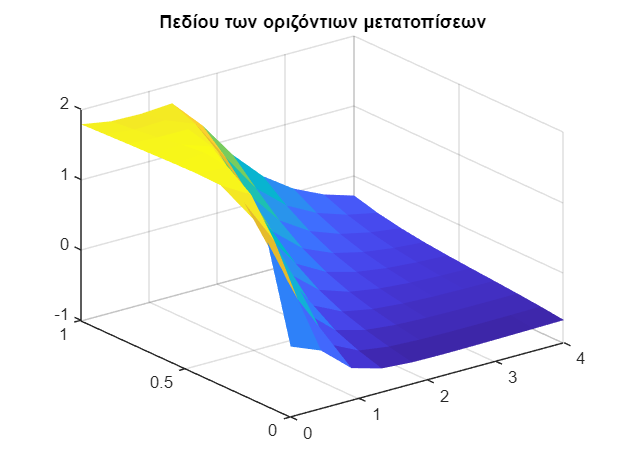

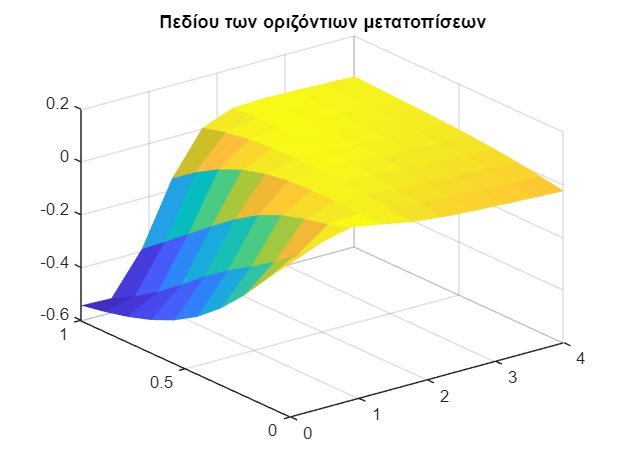

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parameters, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")

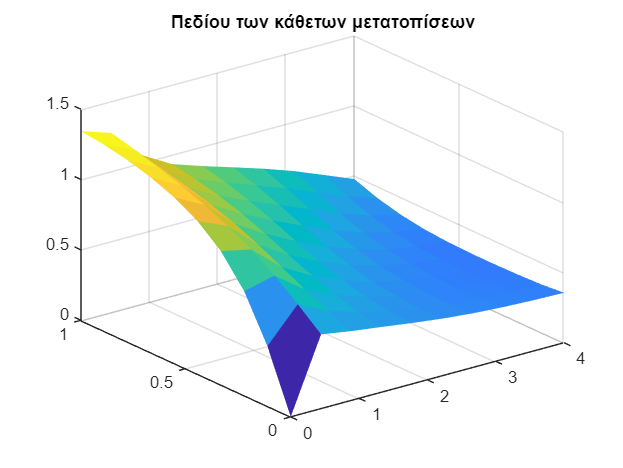

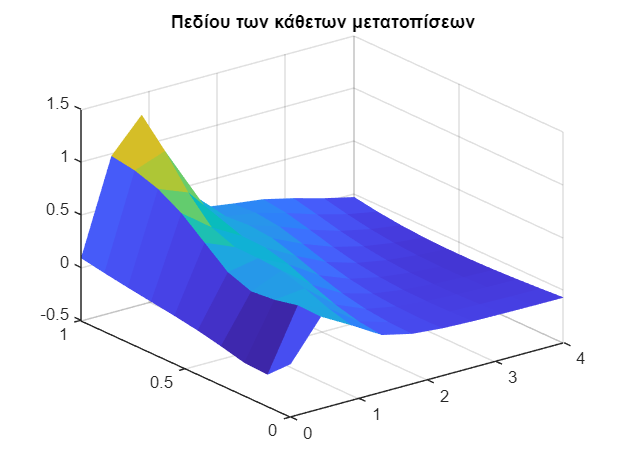

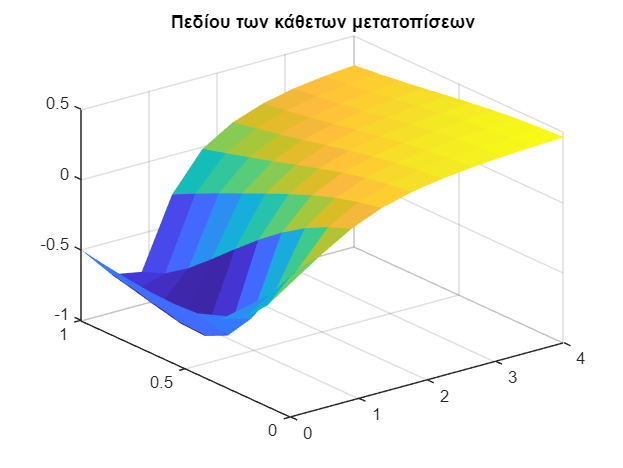

title("Πεδίου των οριζόντιων μετατοπίσεων")
figure
surf(Xvct, Yvct, dispY, "LineStyle","none")

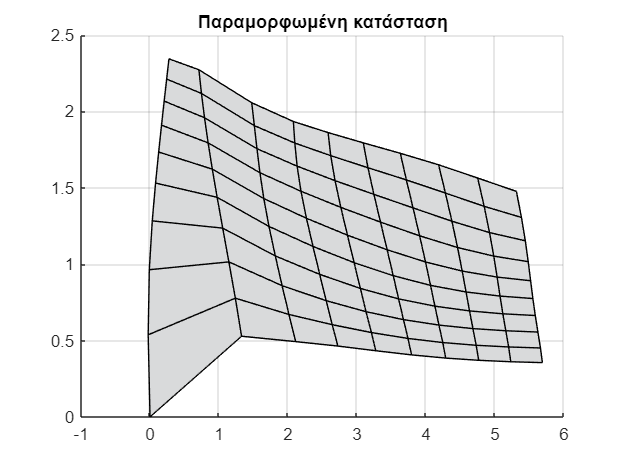

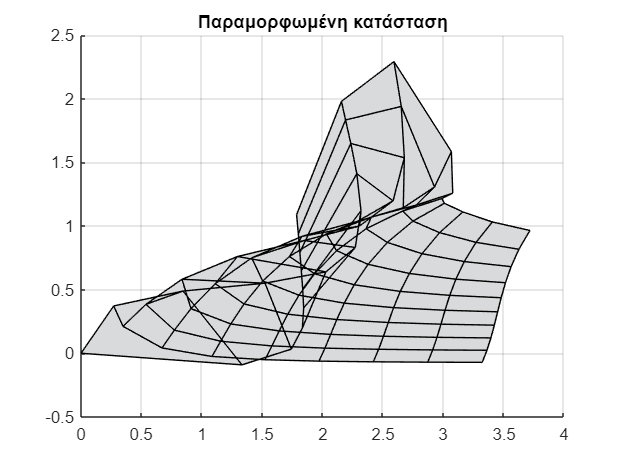

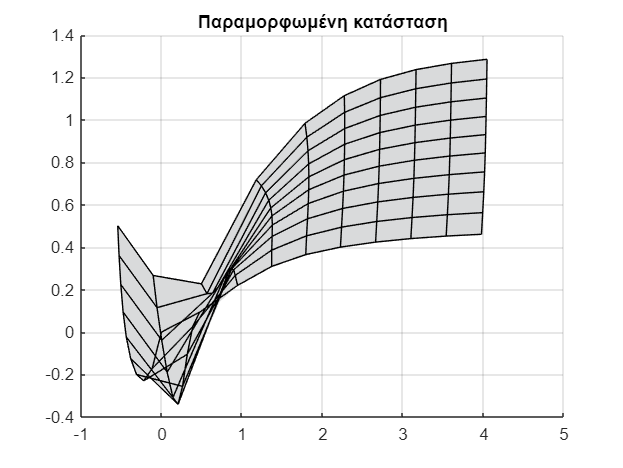

title("Πεδίου των κάθετων μετατοπίσεων")
figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);

view(2)
title("Παραμορφωμένη κατάσταση")

## Train the physics-informed neural network

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Specify the optimization options
opts = optimoptions('fmincon', ... % fminunc
    'HessianApproximation', 'lbfgs', ...
    'MaxIterations', 1000 , ... % 7500
    'MaxFunctionEvaluations', 1000, ... % 7500
    'OptimalityTolerance', 1e-12, ...
    'SpecifyObjectiveGradient', true, ...
    'UseParallel', false, ...
    'Display', 'iter');

% %% Train the network using fmincon

% % extract data and names from the parameters
[parametersV_init,parameterNames,parameterSizes] = parameterStructToVector( ...
    parameters);
parametersV_init = extractdata(parametersV_init);

% % Convert the training data to dlarray objects with format 'CB' (channel, batch).
dlX = dlarray(X,'CB');
dlY = dlarray(Y,'CB');
dlX0BC = dlarray(X0BC,'CB');
dlY0BC = dlarray(Y0BC,'CB');
dlU0BC = dlarray(U0BC,'CB');
dlX_Neumann = dlarray(X_Neumann, 'CB');
dlY_Neumann = dlY0BC;

%%Create a function handle with one input that defines the objective function.
objFun = @(parameters) objectiveFunction(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, dlX_Neumann, dlY_Neumann, P,  ...
    parameterNames, parameterSizes, propStruct, possiblePenaltyFactor, calculateNorms, iterator);

% Update the learnable parameters using the fmincon function
parametersConv = fmincon(objFun, parametersV_init, [], [], [], [], [], [], [], ...
    opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.131459e+15    0.000e+00    4.226e+15
    1      11    1.432956e+15    0.000e+00    2.038e+15    8.822e-01
    2      12    2.066309e+14    0.000e+00    3.343e+14    3.204e-01
    3      13    1.318336e+14    0.000e+00    2.230e+14    5.988e-02
    4      14    4.859574e+13    0.000e+00    9.567e+13    1.348e-01
    5      15    2.490073e+13    0.000e+00    7.213e+13    8.814e-02
    6      16    9.386694e+12    0.000e+00    2.752e+13    1.270e-01
    7      17    6.188566e+12    0.000e+00    1.018e+13    6.337e-02
    8      18    5.014391e+12    0.000e+00    1.165e+13    3.778e-02
    9      19    2.844865e+12    0.000e+00    8.210e+12    1.200e-01
   10      20    1.607213e+12    0.000e+00    9.861e+12    9.781e-02
   11      21    1.226721e+12    0.000e+00    5.306e+12    4.447e-02
   12      22    7.481933e+11    0.000e+00    2

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    5.693658e+15    0.000e+00    6.844e+15
    1       6    2.514796e+15    0.000e+00    1.728e+16    2.823e+01
    2       7    2.289951e+12    0.000e+00    2.052e+09    2.447e+01
    3       8    2.289951e+12    0.000e+00    2.052e+09    1.849e-06
    4       9    2.289951e+12    0.000e+00    2.052e+09    9.244e-06
    5      10    2.289950e+12    0.000e+00    2.052e+09    4.622e-05
    6      11    2.289948e+12    0.000e+00    2.049e+09    2.310e-04
    7      12    2.289936e+12    0.000e+00    2.035e+09    1.154e-03
    8      13    2.289876e+12    0.000e+00    1.965e+09    5.732e-03
    9      14    2.289617e+12    0.000e+00    1.630e+09    2.777e-02
   10      15    2.288995e+12    0.000e+00    3.816e+08    1.199e-01
   11      16    2.288920e+12    0.000e+00    5.416e+08    4.832e-02
   12      17    2.288721e+12    0.000e+00    1

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.783053e+18    0.000e+00    1.418e+19
    1      14    4.653582e+17    0.000e+00    5.103e+18    1.103e-01
    2      15    8.781883e+16    0.000e+00    5.308e+17    3.160e-02
    3      16    8.245057e+16    0.000e+00    3.226e+17    2.948e-03
    4      17    7.778858e+16    0.000e+00    3.234e+17    3.774e-03
    5      18    6.279736e+16    0.000e+00    6.003e+17    1.559e-02
    6      19    4.146210e+16    0.000e+00    8.606e+17    2.734e-02
    7      20    1.473979e+16    0.000e+00    5.917e+17    4.136e-02
    8      22    8.914737e+15    0.000e+00    4.516e+17    2.175e-02
    9      23    4.457555e+15    0.000e+00    5.490e+16    1.109e-02
   10      24    4.370918e+15    0.000e+00    5.456e+16    9.799e-04
   11      25    4.075898e+15    0.000e+00    6.503e+16    2.873e-03
   12      26    3.513687e+15    0.000e+00    1

% parametersVConv = fminunc(objFun, parametersV, opts);

% % For prediction convert the vector of parameters to a structure
parametersConv = parameterVectorToStruct(parametersConv, ...
    parameterNames, parameterSizes);

% % Export network into dat file for future use
% save ('2D_Beam.mat', 'parameters');
% 
% %% Auxiliary functions
%

## Test the converged network

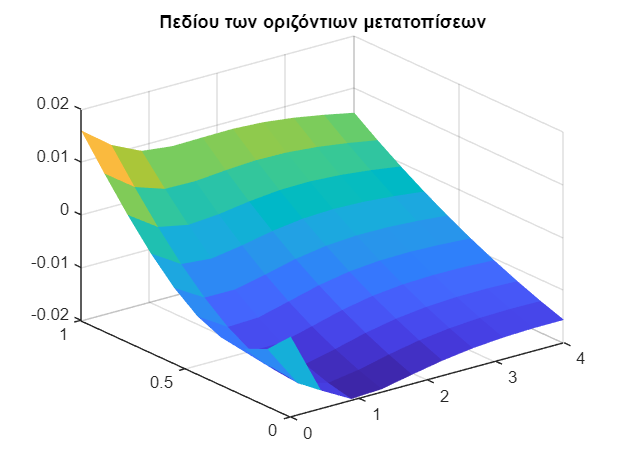

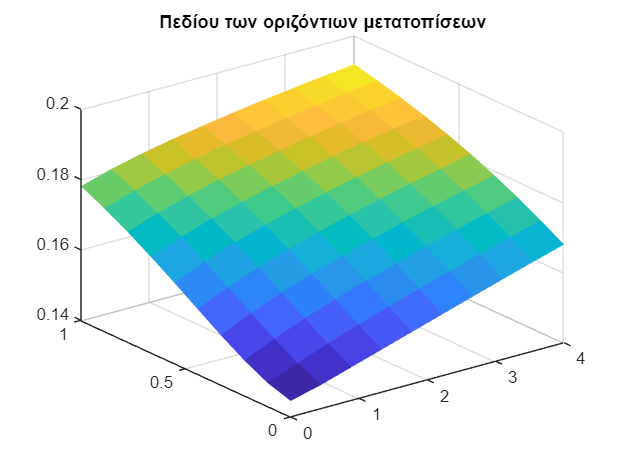

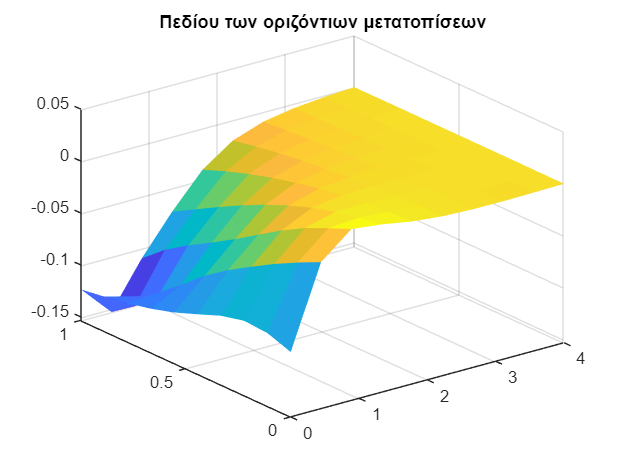

% dlU_test = model(parameters, dlarray(0.5, 'CB'), dlarray(0.1, 'CB'))
numPtsX = 10;
numPtsY = 10;
dX = (XComp(1, 2) - XComp(1, 1))/(numPtsX - 1);
dY = (YComp(1, 2) - YComp(1, 1))/(numPtsY - 1);
Xvct = repmat(XComp(1, 1):dX:XComp(1, 2), numPtsX, 1);
Yvct = repmat(transpose(YComp(1, 1):dY:YComp(1, 2)), 1, numPtsY);
dispX = zeros(numPtsX, numPtsY);
dispY = zeros(numPtsX, numPtsY);

for jj = 1:numPtsY
    for ii = 1:numPtsX
        disp = extractdata(model(parametersConv, dlarray(Xvct(ii, jj), 'CB'), dlarray(Yvct(ii, jj), 'CB')));
        dispX(ii, jj) = disp(1, 1);
        dispY(ii, jj) = disp(2, 1);
    end
end

figure
surf(Xvct, Yvct, dispX, "LineStyle","none")

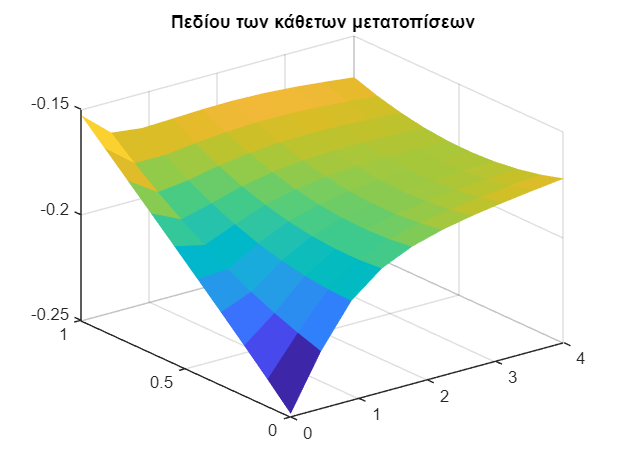

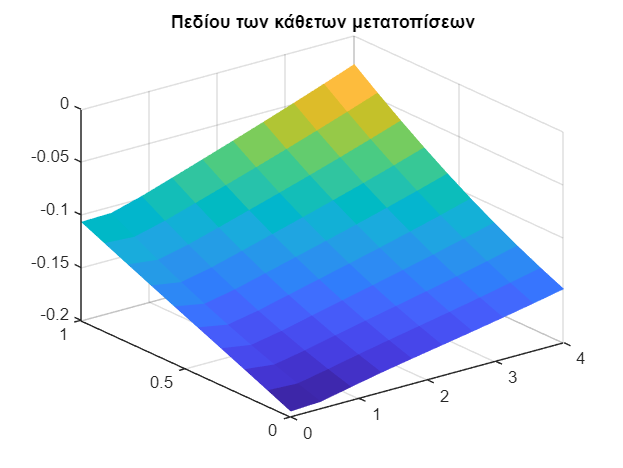

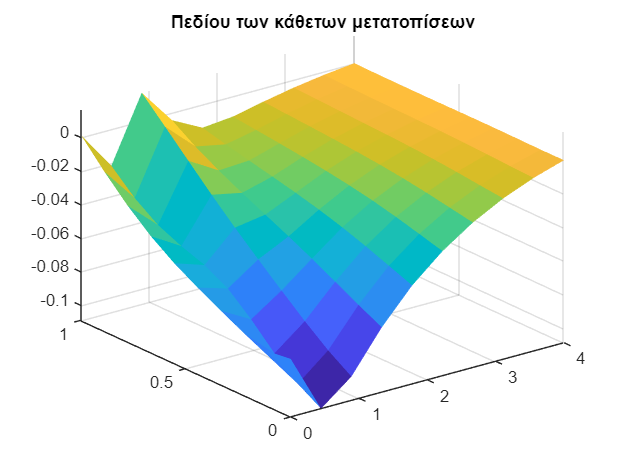

title("Πεδίου των οριζόντιων μετατοπίσεων")
figure
surf(Xvct, Yvct, dispY, "LineStyle","none")

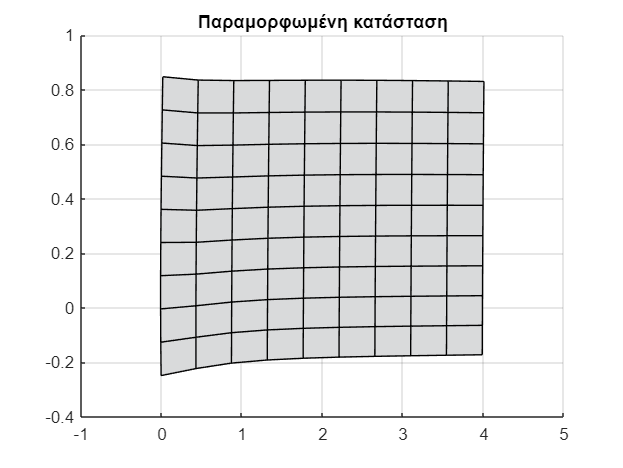

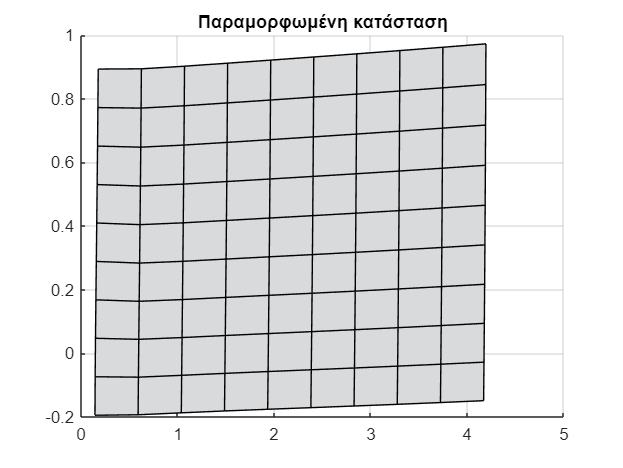

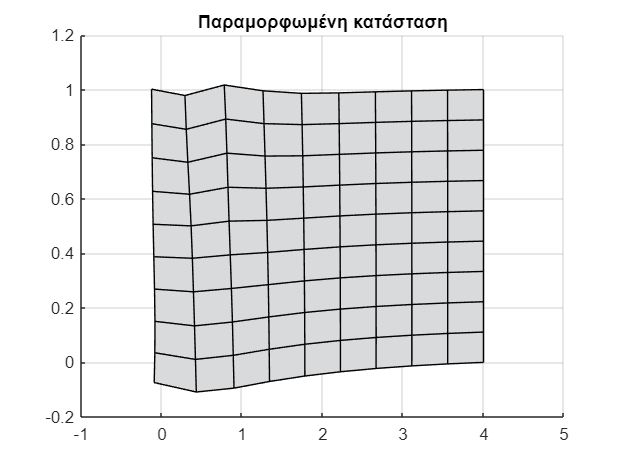

title("Πεδίου των κάθετων μετατοπίσεων")
figure
Xvct_curr = Xvct + dispX;
Yvct_curr = Yvct + dispY;

surf(Xvct_curr, Yvct_curr, zeros(numPtsX, numPtsY), "FaceColor", [217 218 219]/255);

view(2)
title("Παραμορφωμένη κατάσταση")

## Calculate L**2-Norm**

% Define number of Gauss points in which to calculate the norm
numGaussPts = 20;
[GP, GW] = getGaussPointsAndWeightsOverUnitDomain(numGaussPts);

x = repmat(GP, numGaussPts, 1);
y = repmat(transpose(GP), 1, numGaussPts);

% x = repmat(-1:dx:1, numGaussPts, 1);
% y = repmat(transpose(-1:dy:1), 1, numGaussPts);
result = 0;

for jj = 1:numGaussPts
    for ii = 1:numGaussPts
            result = result +  detJ*GW(jj)*GW(ii)*(extractdata(model(parametersConv, dlarray(x(ii, jj), 'CB'), dlarray(y(ii, jj), 'CB')))-vpa(subs(U_analytical, [x1 x2], [x(ii, jj) y(ii, jj)]))).^2;
    end
end
result = sqrt(result);
% for jj = 1:numGaussPts
%     for ii = 1:numGaussPts
%             result = result +  (extractdata(model(parametersConv, dlarray(x(ii, jj), 'CB'), dlarray(y(ii, jj), 'CB')))-vpa(subs(U_analytical, [x1 x2], [x(ii, jj) y(ii, jj)]))).^2
%     end
% end
%%The L2 norm is:

## Find optimal penalty factor (PART B)

calculateNorms(iterator) = norm(result);
end

%% minimum L2 error
[minimumL2, indexFound]= min(calculateNorms);
optimalFactor = possiblePenaltyFactor(indexFound)

optimalFactor = 0.3710

## Define the objective function that optimizes for the weights and biases

function [loss, gradientsV] = objectiveFunction ...
    (parametersV, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, dlX_Neumann, dlY_Neumann, P, parameterNames, parameterSizes, propStruct, possiblePenaltyFactor, calculateNorms, iterator)

    % Convert parameters to structure of dlarray objects
    parametersV = dlarray(parametersV);
    parameters = parameterVectorToStruct(parametersV, parameterNames, ...
        parameterSizes);
    % 
    % Evaluate model gradients and loss
    [gradients, loss] = dlfeval(@modelGradients, parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, dlX_Neumann, dlY_Neumann, P,  ...
        propStruct, possiblePenaltyFactor, calculateNorms, iterator);    
    % Return loss and gradients for fmincon
    gradientsV = parameterStructToVector(gradients);
    gradientsV = extractdata(gradientsV);
    loss = extractdata(loss);
end

## Function that returns the loss and its gradient with respect to the weights and biases

function [gradients,loss] = modelGradients(parameters, dlX, dlY, dlX0BC, dlY0BC, dlU0BC, dlX_Neumann, dlY_Neumann, P, propStruct, possiblePenaltyFactor, calculateNorms, iterator)
        % Make predictions with the initial conditions
    dlU = model(parameters, dlX, dlY);

    collPointsForNeumann = length(dlY_Neumann);

    % unit vector 
    n = [0 -1 0]';

    % force vector 
    F = zeros(3, collPointsForNeumann);
    F(2,:) = -P;

$\frac{\partial u_x}{ \partial X}$, $\frac{\partial u_y}{ \partial Y}$, $\frac{\partial u_x}{ \partial Y}$, $\frac{\partial u_y}{ \partial X}$

    d_dlUX_dx = dlgradient(sum(dlU(1, :),'all'), dlX, 'EnableHigherDerivatives', true);
    d_dlUY_dy = dlgradient(sum(dlU(2, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUX_dy = dlgradient(sum(dlU(1, :),'all'), dlY, 'EnableHigherDerivatives', true);
    d_dlUY_dx = dlgradient(sum(dlU(2, :),'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial^2 X}$, $\frac{\partial^2 u_y}{ \partial^2 Y}$, $\frac{\partial^2 u_x}{ \partial^2 Y}$, $\frac{\partial^2 u_y}{ \partial^2 X}$

    dd_dlUX_dxdx = dlgradient(sum(d_dlUX_dx, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dydy = dlgradient(sum(d_dlUY_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydy = dlgradient(sum(d_dlUX_dy, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdx = dlgradient(sum(d_dlUY_dx, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial^2 u_x}{ \partial X \partial Y}$, $\frac{\partial^2 u_x}{ \partial Y \partial X}$,   $\frac{\partial^2 u_y}{ \partial X \partial Y}$, $\frac{\partial^2 u_y}{ \partial Y \partial X}$

    dd_dlUX_dxdy = dlgradient(sum(d_dlUX_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUX_dydx = dlgradient(sum(d_dlUX_dy, 'all'), dlX, 'EnableHigherDerivatives', true);
    dd_dlUY_dxdy = dlgradient(sum(d_dlUY_dx, 'all'), dlY, 'EnableHigherDerivatives', true);
    dd_dlUY_dydx = dlgradient(sum(d_dlUY_dy, 'all'), dlX, 'EnableHigherDerivatives', true);

$\frac{\partial \sigma _{xx}}{ \partial X}$, $\frac{\partial \sigma _{yy}}{ \partial Y}$, $\frac{\partial \sigma _{xy}}{ \partial Y}$, $\frac{\partial \sigma _{yx}}{ \partial X}$, σ

    d_Sxx_dx = (propStruct.E/(1-propStruct.v^2))*(dd_dlUX_dxdx + propStruct.v*dd_dlUY_dydx);
    d_Syy_dy = (propStruct.E/(1-propStruct.v^2))*(propStruct.v*dd_dlUX_dxdy + dd_dlUY_dydy);
    
    d_Sxy_dy = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydy + dd_dlUY_dxdy);
    d_Syx_dx = (propStruct.E/(2*(1+propStruct.v)))*(dd_dlUX_dydx + dd_dlUY_dxdx);

Neumann -----------

    dlU_N = model(parameters, dlX_Neumann, dlY_Neumann);

    d_dlUX_dx_N = dlgradient(sum(dlU_N(1, :),'all'), dlX_Neumann, 'EnableHigherDerivatives', true);
    d_dlUY_dy_N = dlgradient(sum(dlU_N(2, :),'all'), dlY_Neumann, 'EnableHigherDerivatives', true);
    d_dlUX_dy_N = dlgradient(sum(dlU_N(1, :),'all'), dlY_Neumann, 'EnableHigherDerivatives', true);
    d_dlUY_dx_N = dlgradient(sum(dlU_N(2, :),'all'), dlX_Neumann, 'EnableHigherDerivatives', true);

    Sxx = (propStruct.E/(1-propStruct.v^2))*(d_dlUX_dx_N + propStruct.v*d_dlUY_dy_N);
    Syy = (propStruct.E/(1-propStruct.v^2))*(propStruct.v*d_dlUX_dx_N + d_dlUY_dy_N);
    Sxy = (propStruct.E/(2*(1+propStruct.v)))*(d_dlUX_dy_N + d_dlUY_dx_N);


$$f=\textrm{div}\sigma +b$$


    divStress = [d_Sxx_dx + d_Sxy_dy; d_Syy_dy + d_Syx_dx];
    b_const = - propStruct.p*propStruct.g;
    b = zeros(2, length(dlX));
    b = dlarray(b, 'CB');
    b(2, :) = b_const;

    % equilibrium eq.
    f = divStress + b;
%     f = divStress;
    
    %surf here!!!
    %loss f
    zeroTarget = zeros(size(f), 'like', f);
    lossF = mse(f, zeroTarget);


    % Compute the system response at the beam's right edge (Dirichlet)
    dlUBC = model(parameters, dlX0BC, dlY0BC);
    lossU = mse(dlUBC, dlU0BC);

    % Compute the system response at the beam's left edge (Neumann)
    %% σ*n = f
    lossN = mse([Sxx*n(1)+Sxy*n(2); Sxy*n(1) + Syy*n(2)] , [F(1,:); F(2,:)]);

    % Total loss when searching for optimal penalty factor
    loss = lossF + possiblePenaltyFactor(iterator)*lossU + 4*lossN;
    
     % Total loss when having already found penalty optimal factor
    %optimalDirichletFactor = 1e10;
    %optimalNeumannFactor =1;
    %loss = lossF + optimalDirichletFactor*lossU + optimalNeumannFactor*lossN;

% Calculate gradients with respect to the learnable parameters.
    gradients = dlgradient(loss, parameters);
end

## Feed-forward (model) function for the neural network

function dlU = model(parameters, X, Y)

    dlXY = [X; Y];
    numLayers = numel(fieldnames(parameters))/2;
    
    % First fully connect operation.
    weights = parameters.fc1_Weights;
    bias = parameters.fc1_Bias;
    dlU = fullyconnect(dlXY,weights,bias);
    
%     % tanh and fully connect operations for remaining layers.
    for i = 2:numLayers
        name = "fc" + i;
    
        dlU = tanh(dlU);
    
        weights = parameters.(name + "_Weights");
        bias = parameters.(name + "_Bias");
        dlU = fullyconnect(dlU, weights, bias);
    end
    
end

## **Calculate the optimal penalty factor**

function transformationResults = coordinateTransformationToXiAndEta(x, y)   
        Xi=[-1; 1];
        Eta = [-1; 1];
        syms scale_x const_x scale_y const_y
        X = scale_x*x+const_x;
        Y = scale_y*y+const_y;
        eqns = [X == Xi, Y == Eta];
        r = solve(eqns, [scale_x const_x scale_y const_y]);
        transformationResults = r;
end

function detJ = determinantOfJacobian(results)
    syms Xi Eta
    x = (Xi-results.const_x)/results.scale_x;
    y = (Eta-results.const_y)/results.scale_y;
    J = [diff(x, Xi) diff(y,Xi);
           diff(x,Eta) diff(y,Eta)];
    detJ = det(J);
end